## **基于 PSO 的聚类示例**

`用粒子群优化（PSO）来寻找聚类中心（centroids）`

`对 IRIS 数据集（或其子维度）进行聚类`

`提供了用 k-means 初始化（hybrid_pso）和手动初始化的选项`

`并在迭代过程中可视化粒子/质心及（可选）保存成视频`

### 1. `清空`工作区变量 关闭所有绘画窗口

clear;
close all;

### 2.  固定随机数种子 以便结果可复现

rng('default')              % 用于结果复现

### 3. `粒子群初始化`

centroids = 2;              % 要寻找的簇或者质心数量
dimensions = 2;             % 各个簇的维度
particles = 20;             % 粒子数（每个粒子代表一个完整的质心集合 即一个解）
iterations = 50;            % PSO优化迭代次数
simtime = 0.01;             % 每秒迭代之间pause的秒数（用于可视化延时）
dataset_subset = 2;         % 用于从IRIS 数据选择不同特征列的偏移量（0/1/2）配合维度用
write_video = false;        % 是否将每帧写入视频文件
hybrid_pso = true;          % 是否运行kmeans 并将结果作为第一个粒子的初始位置（混合初始化）
manual_init = false;        % 是否允许手动在figure上用鼠标选择初始质心（仅2D/3D可用）

### 4. 视频写入准备

if write_video
    writerObj = VideoWriter('PSO.avi');
    writerObj.Quality=100;
%     writerObj.FrameRate=30;
    open(writerObj);
end

### 5. 载入数据（IRIS 数据集）并裁剪维度

load fisheriris.mat
meas = meas(:,1+dataset_subset:dimensions+dataset_subset); % be careful
dataset_size = size (meas); % = (样本数, 簇维度)

`meas` 是 150×4 的数值矩阵（4 个特征列）这里取了meas 3:4的列子集

### 6. 用 k-means 初始化（混合 PSO）

if hybrid_pso
    fprintf('Running Matlab K-Means Version\n');
    % 'dist', 'sqEuclidean'：使用平方欧氏距离
    % 'start', 'uniform'   ：初始质心均匀初始化（不同于默认 kmeans++）
    % 'display', 'iter'    ：显示迭代信息
    [idx, KMEANS_CENTROIDS] = kmeans(meas, centroids, 'dist', 'sqEuclidean', ...
        'display', 'iter', 'start', 'uniform', 'onlinephase', 'off');
    fprintf('\n');
end

Running Matlab K-Means Version


  iter	 phase	     num	         sum
     1	     1	     150	     268.148
     2	     1	      29	     150.133
     3	     1	      16	     95.1727
     4	     1	       4	     87.3855
     5	     1	       2	     86.3902
Best total sum of distances = 86.3902


调用 MATLAB 内建 `kmeans` 函数对数据做一次 k-means 获取 `KMEANS_CENTROIDS`（`centroids`×`dimensions`）

目的是把 k-means 结果放到 PSO 的某个粒子上，作为良好初始点（可以提高收敛速度/质量）

### 7. PSO 全局参数（惯性、认知、社交权重）

w  = 0.72;                % 惯性因子（保持当前速度的比例）
c1 = 1.49;                % 认知系数（向粒子自身历史最优靠拢）
c2 = 1.49;                % 社交系数（向全局最好靠拢）

根据这篇文章 [http://ieeexplore.ieee.org/stamp/stamp.jsp?tp=&arnumber=1299577&isnumber=28874](http://ieeexplore.ieee.org/stamp/stamp.jsp?tp=&arnumber=1299577&isnumber=28874) 给出的参数设置

### 8. 绘图相关初始化（颜色 句柄）

pc = []; txt = [];        % 用于保存 plot 对象句柄 方便后面 delete(pc) 清理

% 为每个粒子随机生成一个 RGB 颜色（在可视化中给每个粒子的质心用独立颜色）
cluster_colors_vector = rand(particles, 3);

### 9. 绘制数据点（scatter）

fh=figure(1);             % 创建 figure
hold on;                  % 保持 hold on

if dimensions == 3        
    plot3(meas(:,1),meas(:,2),meas(:,3),'k*');
    view(3);
elseif dimensions == 2
    plot(meas(:,1),meas(:,2),'k*');
end                       % 根据维度 画出数据点（黑星 k*）

axis equal;               % 坐标轴等比例

% 设置坐标范围 左右/上下扩展2个单位 并把min/max向量转换成axis所需格式[xmin xmax ymin ymax ...]
axis(reshape([min(meas)-2; max(meas)+2],1,[]));
hold off;

### 10. PSO 数据结构初始化（速度 位置 best fitness 等）

% 三维数组 表示每个粒子中每个质心的速度向量 初始*0.1（较小随机速度）
swarm_vel = rand(centroids, dimensions, particles)*0.1;

% 三维数组 初始为[0,1)随机值 后面会尺度化到数据范围
swarm_pos = rand(centroids, dimensions, particles);

% 初定义二维 但后面作为swarm_best(:,:,particle)被赋值时会动态扩展成三维
swarm_best = zeros(centroids, dimensions);

% 存放每个数据点对每个粒子分配到的质心的索引（每列为某粒子的分配结果）
c = zeros(dataset_size(1), particles);

% 向量 存每个特征的范围（长度 = dimensions）
ranges = max(meas)-min(meas); 

% 把 swarm_pos从[0,1)线性缩放到[min(meas),max(meas)]区间上 【确保初始质心在数据边界内】
swarm_pos = swarm_pos .* repmat(ranges,centroids,1,particles) + repmat(min(meas),centroids,1,particles);

% 为每个粒子初始化 fitness 为无穷大（越小越好 脚本用最小化）
swarm_fitness(1:particles)=Inf;

### `11. `用 k-means 结果初始化第一个粒子

if hybrid_pso
    % 把第6步得到的KMEANS_CENTROIDS直接设为第一个粒子的质心集合
    swarm_pos(:,:,1) = KMEANS_CENTROIDS; 
end

提供一个好的初始解（可能提高最终收敛质量）

### 12. 手动初始化（仅 2D或3D）

if manual_init
    if dimensions == 3
        % 直接写死两个质心坐标（硬编码示例）
        swarm_pos(:,:,1) = [6 3 4; 5 3 1]; 
    elseif dimensions == 2
        % 调用 ginput(2) 允许用户在figure上点击2个点作为第一个粒子的质心位置
        swarm_pos(:,:,1) = ginput(2);
    end
end

注意：`ginput(2)` 返回 2×2 矩阵（每行一个点的 x,y），如果 `centroids` 不为 2，这里会出错或不一致

### 13. 主循环：迭代 PSO（距离计算 → 分配 → 评估 → 更新）

for iteration = 1:iterations
    % 计算到所有质心的欧氏距离
    distances = zeros(dataset_size(1),centroids,particles);
    % 遍历每个粒子（即每个解）
    for particle = 1:particles
        % 遍历该粒子的每个质心
        for centroid = 1:centroids
            distance = zeros(dataset_size(1),1);
            % 遍历数据集中的每个数据向量 算欧氏距离
            for data_vector = 1:dataset_size(1)
                distance(data_vector,1) = norm(swarm_pos(centroid,:,particle) - ...
                    meas(data_vector,:));
            end
            distances(:,centroid,particle)=distance;
        end
    end

    % 将每个样本分配到最近的聚类中心
    % distances(i,j,particle) 表示第 i 个样本到第 j 个质心的距离
    % min(distances(:,:,particle),[],2) 沿着第二维（即每个样本到所有质心的距离）找到最小值及其索引
    % 把最近质心的索引放入 c(:,particle)
    for particle = 1:particles
        [value, index] = min(distances(:,:,particle),[],2);
        c(:,particle) = index;
    end

    % 删除上一帧的绘图句柄（保持动画更新）
    delete(pc); delete(txt);
    pc = []; txt = [];
    
    % 内层循环绘制每个粒子中每个质心的标记（*）
    % 但只有当该质心在该粒子中至少有一个点被分配（any(c(:,particle) == centroid))时才画
    hold on;
    for particle = 1:particles
        for centroid = 1:centroids
            if any(c(:,particle) == centroid)
                if dimensions == 3
                    pc = [pc plot3(swarm_pos(centroid,1,particle), swarm_pos(centroid,2,particle), ...
                        swarm_pos(centroid,3,particle), '*', 'color', cluster_colors_vector(particle,:))];
                elseif dimensions == 2
                    pc = [pc plot(swarm_pos(centroid,1,particle), swarm_pos(centroid,2,particle), ...
                        '*', 'color', cluster_colors_vector(particle,:))];
                end
            end
        end
    end
    set(pc,{'MarkerSize'},{12})  % 调整大小
    hold off;
 
    % 计算每个粒子的局部 和全局 fitness=swarm_fitness（用于PSO引导）
    % 计算每个粒子（一个解）的聚类质量作为 fitness（越小越好）
    average_fitness = zeros(particles,1);
    for particle = 1:particles
        for centroid = 1 : centroids
            % 若质心有被分配到点 计算 local_fitness 为该簇内样本到质心的平均距离（mean(distances(...))）
            % 然后把这些平均距离求和
            if any(c(:,particle) == centroid)
                local_fitness=mean(distances(c(:,particle)==centroid,centroid,particle));
                average_fitness(particle,1) = average_fitness(particle,1) + local_fitness;
            end
        end
        % average_fitness(particle) 除以 centroids 得到最终的平均值
        % 注意：始终除以 centroids 而不是"有成员的簇数" 若某簇没有成员会跳过该簇的累加
        % 但仍除以centroids 等价于把空簇视为零贡献 可能会偏低地表征fitness 需要改进
        average_fitness(particle,1) = average_fitness(particle,1) / centroids;

        % 如果新计算的 average_fitness 比该粒子之前记录的 swarm_fitness(particle) 更好（更小）
        % 则更新 swarm_fitness 并把这个粒子的当前位置保存为 swarm_best(:,:,particle)（局部最好）
        if (average_fitness(particle,1) < swarm_fitness(particle))
            swarm_fitness(particle) = average_fitness(particle,1);
            swarm_best(:,:,particle) = swarm_pos(:,:,particle);     % LOCAL BEST FITNESS
        end
    end    
    % GLOBAL BEST FITNESS = 所有粒子中最小的 fitness 及其索引 index
    % 把该最优粒子的质心位置作为全局最优位置（用于 social component）
    [global_fitness, index] = min(swarm_fitness);       % GLOBAL BEST FITNESS
    swarm_overall_pose = swarm_pos(:,:,index);          % GLOBAL BEST POSITION
    
    % 输出当前迭代和全局fitness值
    fprintf('%3d. global fitness is %5.4f\n', iteration,global_fitness);            
    %uicontrol('Style','text','Position',[40 20 180 20],'String',sprintf('Actual fitness is: %5.4f', global_fitness),'BackgroundColor',get(gcf,'Color'));        
    % 给可视化一点时间
    pause(simtime);
        
    % 从 figure fh 捕获当前帧并写入视频文件
    if write_video
        frame = getframe(fh);
        writeVideo(writerObj,frame);
    end
       
    % 从均匀分布抽样随机数 r1r2（用于速度更新）
    % 注意这里采样的是单个标量 r1r2 用于所有粒子同一份随机数
    % 典型PSO实现中 r1r2 是对每个维度/每个粒子分别采样（rand(centroids,dimensions) 或 rand(size)）
    % 以增加随机性和多样化搜索；在这里使用同一个随机数对所有粒子/维度，搜索随机性较低但实现更简单
    r1 = rand;
    r2 = rand;
    
    % 速度和位置更新（核心 PSO 公式）
    % 没有对速度进行限制（vmax）或对位置进行边界剪切（如果越界会离开数据范围），若需要可添加约束
    for particle = 1:particles        
        % 保持之前速度的一部分
        inertia = w * swarm_vel(:,:,particle); 
        % 粒子向自己的历史最优位置靠拢（个人经验项）
        cognitive = c1 * r1 * (swarm_best(:,:,particle)-swarm_pos(:,:,particle));
        % 粒子向全局最优靠拢（群体经验项）
        social = c2 * r2 * (swarm_overall_pose-swarm_pos(:,:,particle));
        % 合成新的速度
        vel = inertia+cognitive+social;
        % swarm_pos = swarm_pos + vel（位置更新），swarm_vel = vel（速度记忆）
        swarm_pos(:,:,particle) = swarm_pos(:,:,particle) + vel;
        swarm_vel(:,:,particle) = vel;
    end
    % 这里速度/位置的维度是 [centroids × dimensions]
    % （每粒子有 centroids 个质心 每个质心是 dimensions 维向量）    
end

  1. global fitness is 0.4920
  2. global fitness is 0.4920
  3. global fitness is 0.4920
  4. global fitness is 0.4920
  5. global fitness is 0.4903
  6. global fitness is 0.4877
  7. global fitness is 0.4877
  8. global fitness is 0.4877
  9. global fitness is 0.4877
 10. global fitness is 0.4877
 11. global fitness is 0.4877
 12. global fitness is 0.4877
 13. global fitness is 0.4877
 14. global fitness is 0.4877
 15. global fitness is 0.4877
 16. global fitness is 0.4877
 17. global fitness is 0.4877
 18. global fitness is 0.4877
 19. global fitness is 0.4877
 20. global fitness is 0.4877
 21. global fitness is 0.4877
 22. global fitness is 0.4877
 23. global fitness is 0.4877
 24. global fitness is 0.4877
 25. global fitness is 0.4877
 26. global fitness is 0.4877
 27. global fitness is 0.4877
 28. global fitness is 0.4877
 29. global fitness is 0.4877
 30. global fitness is 0.4877
 31. global fitness is 0.4877
 32. global fitness is 0.4877
 33. global fitness is 0.4877
 34. globa

这个实现是直白的循环，计算量较大

可用矢量化（`pdist2` 或矩阵运算）显著加速

例如 `pdist2(meas, swarm_pos(:,:,particle))` 获得 `N×centroids` 的距离矩阵

迭代结束 回到 `for iteration` 的下一次循环；重复上述计算直到达到 `iterations`

### 14. 迭代结束后：绘制最终分配（选择最佳粒子）

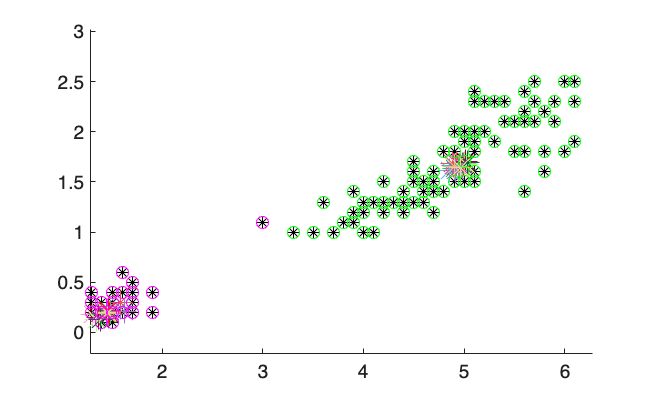

hold on;
% 选择 index（全局最优粒子）并绘制该粒子的簇分配
% 对每个质心 把分配给它的点用 plot(...,'o','color',cluster_colors(centroid)) 标出来
particle = index;

% 字符数组 取 cluster_colors(centroid) 得到字符颜色（例如 'm'）
cluster_colors = ['m','g','y','b','r','c','g'];

for centroid = 1:centroids
    if any(c(:,particle) == centroid)
        if dimensions == 3
            plot3(meas(c(:,particle)==centroid,1), meas(c(:,particle)==centroid,2), ...
                meas(c(:,particle)==centroid,3), 'o', 'color', cluster_colors(centroid));
        elseif dimensions == 2
            plot(meas(c(:,particle)==centroid,1),meas(c(:,particle)==centroid,2), ...
                'o', 'color', cluster_colors(centroid));
        end
    end
end
hold off;


% 注意 cluster_colors 只包含 7 个颜色字符 若 centroids > 7 会重复或导致颜色索引超出范围（错误）
% 建议使用 lines(centroids) 或 hsv 来动态生成颜色向量

### 15. 结束视频写入 打印结束信息

if write_video
    % 写入最后一帧并 close 视频对象
    frame = getframe(fh);
    writeVideo(writerObj, frame);
    close(writerObj);
end
% 打印最终全局 fitness 值
fprintf('\nEnd, global fitness is %5.4f\n', global_fitness);


End, global fitness is 0.4877


**数组维度**：关键数组 `swarm_pos`、`swarm_vel`、`swarm_best` 的维度均为 `[centroids × dimensions × particles]`（`swarm_best` 在声明时是 2D，但随后按 3D 使用，会被自动扩展）。理解这一点有助于读懂索引 `swarm_pos(centroid,:,particle)`

**性能**：距离计算部分是三重循环，数据量或粒子数较大时会非常慢。推荐用 `pdist2` 或矩阵化方式替换 `for data_vector` 循环

如`dist = pdist2(meas, squeeze(swarm_pos(:,:,particle)));` 会返回 `N×centroids` 的距离矩阵

**随机数 r1,r2**：脚本只为迭代采样一次 `r1,r2` 并用于所有粒子；可以考虑改为 `r1 = rand(centroids,dimensions); r2 = rand(centroids,dimensions);` 或 `rand(size(swarm_pos(:,:,particle)))`，得到更多随机性

**fitness 计算小心空簇**：当前实现把簇内平均距离求和后除以 `centroids`（而不管该簇是否有成员），这可能在存在空簇时导致偏差。建议改为除以 `number_of_nonempty_clusters` 或对空簇设置惩罚（比如加大惩罚项），以避免空簇被错误地视为优解

**边界/速度限制**：没有 `vmax` 或位置边界限制，可能导致粒子跑出数据空间。可在更新后加 `swarm_pos = max(min(swarm_pos, max(meas)), min(meas))` 或限制速度 `vel = max(min(vel, vmax), -vmax)`

**可视化**：当前把每个粒子的质心都画在同一张图上，较好用于观察 swarm 的多样性；如果想更清晰，可绘制单独子图或仅绘制若干代表性粒子

**参数可调**：`w`, `c1`, `c2`, `particles` 与 `iterations` 均影响收敛质量与速度，建议做参数敏感性测试